# Using the Simple Game Engine

### Incorporating Graphics by Displaying Image Sprites

Adding graphics to a game or program can help the user to understand, even at a quick glance, all that is going on and how they can interact with it.

While the task of adding graphical user interfaces can seem daunting, there are tools that can make the process much simpler. One such tool is a game engine.

For this course, we are providing you with the simpleGameEngine, a custom sprite mapping program for MATLAB created by a former ENGR 1181 instructor.

This live script will help you understand what sprites are, how simpleGameEngine handles them, how this framework can help you craft your own games, and how to use the four functions of the simpleGameEngine class to create your own graphical user interface.

**1. Create the scene**

The first step when using simpleGameEngine is to create the simpleGameEngine scene object. The scene will be a variable that you will use later; none of the other simpleGameEngine functions work without the scene object.

These objects are not native to MATLAB, so you will need the simpleGameEngine.m file in your filepath to work with them. As part of their basic function, they read from an image file which will also need to be in your filepath. In this example, we are using 'retro_cards.png'. Both files are available on Carmen.

Once both other files are in your filepath, run the code in this section to create your first scene object. All of the arguements will be explained in more detail below.

%{
create a scene using the provided retro cards image
    16x16 pixel-sprites
    magnification = 4
    off-white background
%}
card_scene = simpleGameEngine('retro_cards.png',16,16,4,[245,245,245]);

You will notice card_scene appeared in your workspace, but no graphics were shown yet. The next step will explain how simpleGameEngine interprets graphics.

**2. How to read sprite sheets and display images**

The simpleGameEngine object helps you create graphics by correlating a large number of static images to basic integers. 

Each individual image is called a "sprite", and the file they are stored in is called a "sprite sheet". This is the '.png' file called as the first arguement above.

The number associated with each sprite is based on it's position in the sprite sheet. The top-leftmost sprite is associated with #1, the sprite immediately to the right of that is #2, and so on. Numbering wraps back to the left with each new line, so in sheets like retro_cards.png where there are 10 sprites per row in the sprite sheet, the sprite below #1 is #11.

When using the drawScene function to display these sprites, those numbers are arranged in an array to determine what final, composite image is shown.

Run this section, then open retro_cards.png and compare it to the image displayed below.

%create an array of numbers starting with 1 in the top left, ascending
%across each row of 10, and ending at 100
sprite_sheet_contents = [1:10; 11:20; 21:30; 31:40; 41:50; 51:60; 61:70; 71:80; 81:90; 91:100]

sprite_sheet_contents =      1     2     3     4     5     6     7     8     9    10
    11    12    13    14    15    16    17    18    19    20
    21    22    23    24    25    26    27    28    29    30
    31    32    33    34    35    36    37    38    39    40
    41    42    43    44    45    46    47    48    49    50
    51    52    53    54    55    56    57    58    59    60
    61    62    63    64    65    66    67    68    69    70
    71    72    73    74    75    76    77    78    79    80
    81    82    83    84    85    86    87    88    89    90
    91    92    93    94    95    96    97    98    99   100


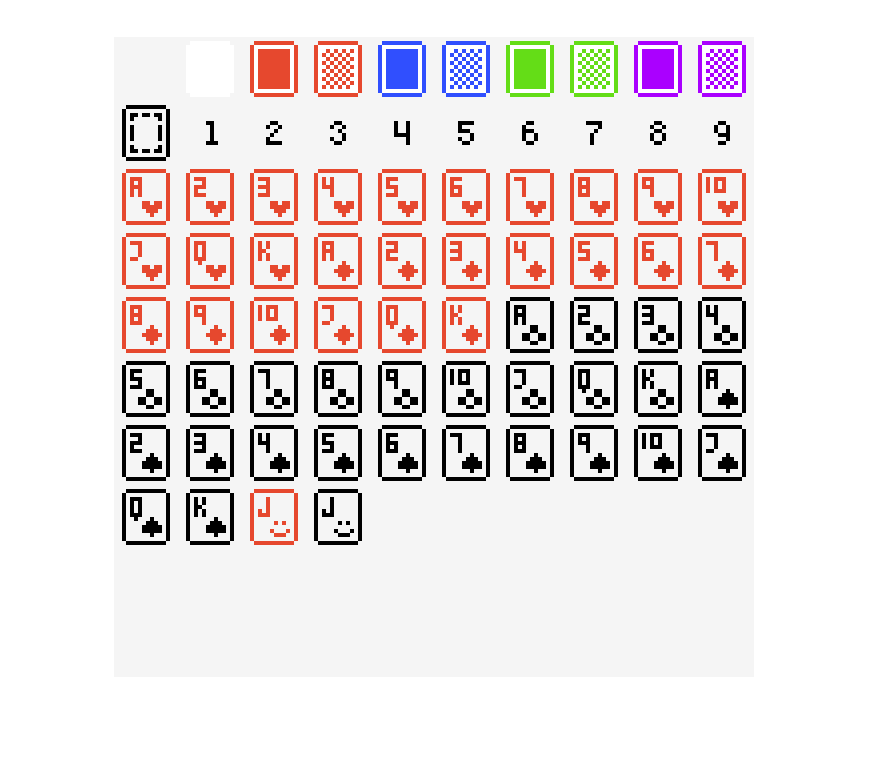

%drawScene needs a simpleGameEngine object as its first arguement, followed
%by at least one array of integers for sprite indexes
drawScene(card_scene,sprite_sheet_contents)

You'll note that sprite 1 looks empty. It is, and this is a common feature of sprite sheets you will encounter or create. Having sprite 1 be a fully transparent sprite can be very helpful for seeing the background or for layering sprites, which we will get to later in this script.

**3. Scene input arguement variation**

When making a simpleGameEngine object, you are also telling it the diemensions of the sprites it will be reading from the sprite sheet in pixels, a magnification factor for display, and a background color. Magnification and background color are both optional input arguements and will default to 1 and black, respectively.

Background color is determined by a colors RGB value, or a 1x3 array of integers between 0 and 255 that express how present red, green, and blue are in the color. As such, the default black is [0, 0, 0], and a white background would be [255, 255, 255]. These values produce standardized colors, so if you have a specific color in mind, you can look up its RGB value online. Alternatively, you can pick a color and see its RGB value at the same time using the text color selector on any Microsoft Office product, then selecting "More Colors..." and "Custom".

Experiment with these parameters by running this section with several different versions of the input arguments, but return it to a 16x16 pixel, magnification 8, white background before proceeding. Make sure to run this section with the reverted settings before moving on.

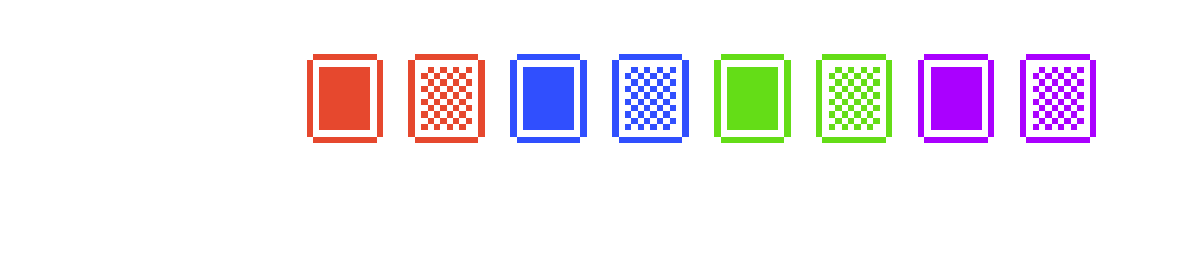

%{
create a scene using the provided retro cards image
    16x16 pixel-sprites
    magnification = 8
    white background (RGB = 255, 255, 255)
%}
card_scene = simpleGameEngine('retro_cards.png',16,16,8,[255,255,255]);
drawScene(card_scene,sprite_sheet_contents(1,:))

**4a. Choose and arrange your sprites**

To add graphics to a program or game, you do not want to display every sprite avaiable, only ones allow the user to understand what is happening at the time.

For instance, in a card game, you would only display the player's hand, not the whole deck.

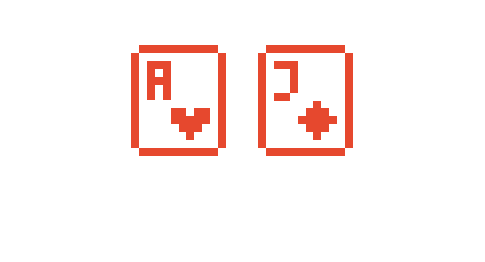

%{
Draw the scene with the Ace of Hearts (sprite #21) and Jack of Diamonds (sprite #44)
%}

drawScene(card_scene, [21, 44])

**4b.**

As sprites appear in the image displayed in the same arrangement their indexes are positioned in the matrix you are displaying, you can add more rows of sprites by adding more rows of numbers.

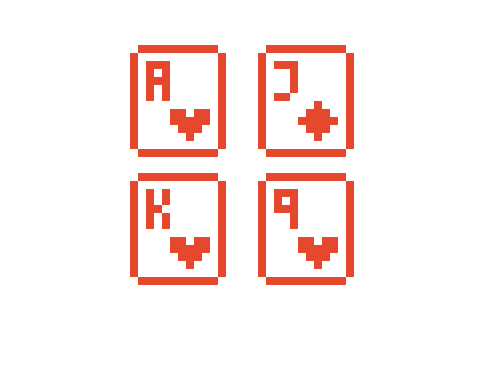

%{
Add a second row of cards to the scene
%}
drawScene(card_scene, [21, 44; 33, 29])

**4c.**

Matricies must be rectangular, so to add one sprite, sprites must be added to the whole row or column. With a blank sprite as sprite 1, it is easy to identify or fill empty spaces in the image you are making.

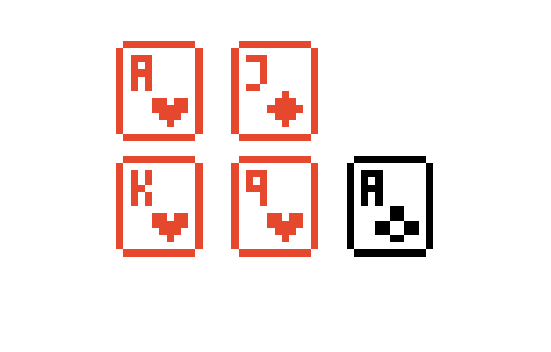

%{
To add another card to the second hand, you must 
also add another sprite to the first hand (it has to be 
a rectangular grid). Use the blank sprite (#1)
%}
drawScene(card_scene, [21, 44, 1; 33, 29, 47])

**You Try It #1:**

Create your own simpleGameEngine scene object with a background color of OSU Grey (**RGB** 167-177-183).

Use the drawScene function to display three rows of sprites to simulate a card game:

1: Five card backs of an opponent's cards

2: Empty space to denote the table

3: Your winning hand (five card sprites of your choosing)

You should save the sprite indexes to an array before displaying them. E.g like drawScene(scene, myArray), not drawScene(scene, [3 4 6]).

%Enter your code here, then run this section



**5. Using sprite sheet structure in your game structure**

Consider the retro_cards.png sprite sheet. It contains:

1 - 20 Sprites that are not cards

21 - 33 Hearts  (Ace through King)

34 - 46 Diamonds (Ace through King)

47 - 59 Clubs (Ace through King)

60 - 72 Spades (Ace through King)

73 - 74 Jokers  (Red, Black)

To pick a card at random from the deck, we would need a random number above 20.

With a repeating pattern of thirteen cards for each of four suits, we can use the choice of card value and card suit to create a card value.

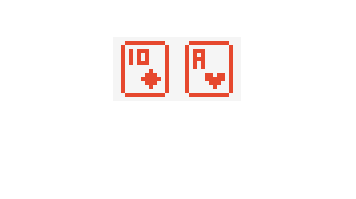

%{
Generate two cards at random
   skip 20 non-card sprites
   choose card value between 1 (Ace) and 13 (King)
   choose card suit from 0 (Hearts), 1 (Diamonds), 2 (Clubs) or 3 (Spades)
%}
skip_sprites = 20;
card_vals = randi(13, 1, 2);
card_suits = randi(4, 1, 2) - 1;

%Sprite numbers start at 21 if card_vals is 1 and card_suits is 0.
%Sprite numbers increase by 1 if card_vals increase by 1.
%Sprite numbers increases by 13 if card_suits increases by 13.
card_sprites = skip_sprites + 13*(card_suits) + card_vals;

drawScene(card_scene, card_sprites)

**You Try It #2:**

Write some code to accomplish this task:

Display four random cards that are all hearts.

Wait for the user to hit a key on the keyboard with this line of code (explained in more detail in section 6 below):

      getKeyboardInput(card_scene);

After a button press, display those same four cards as diamonds.

In the same manner, show the same cards as clubs and then spades.

%Pick four card values and show them in each suit


**5b. Alternative structures for card games**

You may have noticed that when using the method above to generate random cards, you sometimes get the same card twice. For most card games, this is undesirable, as the assumption that each card in the deck is unique is an important aspect of the game.

The randperm() function can help with this, as it gives a random ordering of numbers without repeating any of them.

Note the differences in this example where the player is drawing 7 cards from a 10 card deck:

%make a hand using randi that includes 7 values between 1 and 10
iHand = randi(10, 1, 7)  

iHand =      8     6     2     7     2     2     1


%make a hand using randperm that includes 7 values between 1 and 10
pDeck = randperm(10);
pHand = pDeck(1:7)

pHand =      1     2     3     6     7     5     4


While it is possible you saw no repeats in iHand, you definitely will not have seen any in pHand. These numbers will randomize the order of items without repeating any, but extra steps must then be taken to give the items meaning.

One way to do this is to make extra arrays with the meaning baked in.  If these ten cards were the Ace through 5 of Hearts and Clubs, then those arrays might looks like this:

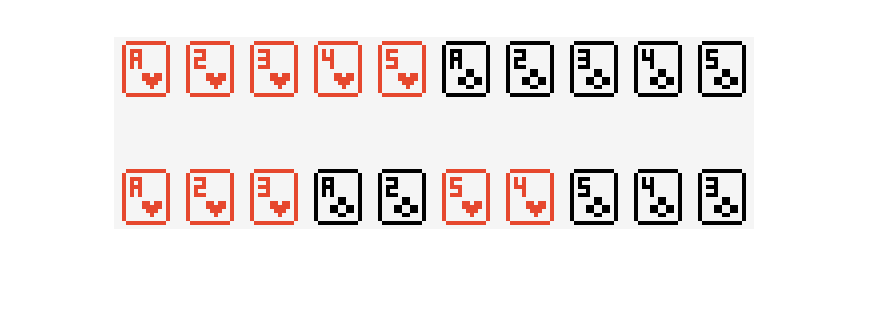

pSuits = [repelem(0,5), repelem(2,5)]; %Five zeros for Hearts, Five twos for Clubs
pVals = repmat([1:5],1,2); %Values are 1 through 5, then 1 through 5 again
pSprites = 20 + 13*(pSuits) + pVals; %Correlate these to sprites in the same ways

%Use the values in the Hand array as indexes the meaning arrays above
pDisplay = [pSprites; %Start with cards in their unshuffled order
           ones(1,10); %Leave a line of blank space
           pSprites(pDeck)]; %Use the array created with randperm() as an order for the sprites
drawScene(card_scene,pDisplay)

In this example, we used four different arrays to keep track of card suits, values, sprite number, and order. This isn't strictly necessary as most of these can be discovered with some basic math functions since we know the repeating patterns of the sprites. If we call the Ace of Hearts card 1 and the King of Spades card 52:

The sprites are already arranged in this order and we know that the first card (or card 1) is sprite 21, so we can find any sprite ID using:

       SpriteID = CardID + 20;

We know that cards 1-13 are Hearts, 14-26 are Diamonds, etc. Dividing these numbers by 13 and rounding up gives us a 1 for every Heart, a 2 for every Diamond, etc. We could thus retrieve information about the suit using:

      SuitID = ceil(CardID/13);   %If we are okay with changing to a 1 = Heart, 2 = Diamond, 3 = Club, 4 = Spade scheme

         OR

     SuitID = ceil(CardID/13) - 1; %If we want to stick with 0 = Heart, 1 = Diamond, etc.

We know that the pattern of values resets every thirteen cards (Ace at 1 through King at 13, then Ace at 14 through King at 26). Here, dividing by 13 and taking the remainder will uniquely identify each card value. While there are small differences, the functions rem() and mod() both give remainders. If using mod(), the code for finding a card's value might look like:

     ValID = mod(CardID/13); %This will result in the value of Aces returning as 1, Queens returning as 12, and Kings returning as 0.

          OR

    ValID = mod((CardID-1)/13) + 1; %Here, the mod() function returns Aces as 0 and Kings as 12, then the +1 sets Aces to 1 and Kings to 13.

### 6. Keyboard Input

The simpleGameEngine comes with built-in keyboard and mouse input functions that allow the user to interact with the images they see.

For keyboard input, you can store the identity of a key pressed to a variable using the function getKeyboardInput, which takes your scene as its input variable.

The identity of the key pressed will be stored as a string which can 

First, however, your user will need to know that they are expected to press a key, either through use of fprintf, a function that adds text to a plot such as title or xlabel, a user's manual, or some other clear prompting.

Run this section several times, noting what the "key" variable gets set to each time.

    drawScene(card_scene, card_sprites)
    fprintf('Do you want to hit? (space bar = hit, escape = stay)\n')

Do you want to hit? (space bar = hit, escape = stay)


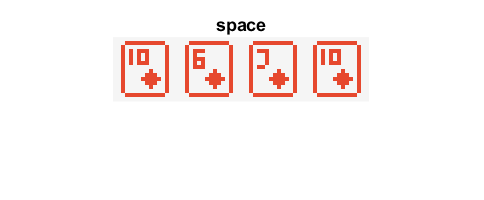

    
    %{
    Wait for a keystroke (other code will not run until a key is pressed)
    If a letter or number is struck, the returned value will be
    that letter or number (e.g. 'a', 'b', 'c', ..., '1', '2', '3', ...)
    For special characters, it will be a word, e.g. 'space', 'escape'
    %}
    key = getKeyboardInput(card_scene);
    
    pause(0.2); %This waits for another 0.2 seconds after the key is pressed, helpful for key de-bouncing
    
    title(key); %Prints the value of 'key' above the image created by the sprites

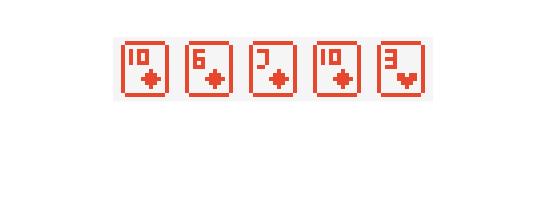

    if strcmp(key, 'space')
        hit = 1;
        card_vals = [card_vals, randi(13)];
        card_suits = [card_suits, randi(4)-1];
        card_sprites = skip_sprites + 13*(card_suits) + card_vals;
        drawScene(card_scene, card_sprites)
    elseif strcmp(key, 'escape')
        hit = 0;
        fprintf("Player Stays.")
    end

### 6. Detecting Mouse Clicks

The other simpleGameEngine input function is getMouseInput.

getMouseInput also takes the scene object as its input, but it has between one and three outputs.

If saved to one output element (e.g. r = getMouseInput(card_scene);), then only the first output will be saved. This is the row of sprites that was clicked.

If it is saved to variables in a 1x3 array (e.g. [r, c, b] = getMouseInput(card_scene); as below), then it will store the row clicked, the column clicked, and what mouse button was used.

The row and column data correspond directly to the row and column locations of the sprite clicked. As such, they can be used as indexes to affect the number stored in the matrix used for display.

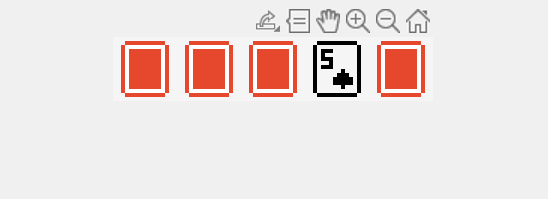

%Generate a new hand of cards

card_vals = randi(13, 1, 5);
card_suits = randi(4, 1, 5) - 1;

card_sprites = skip_sprites + 13*(card_suits) + card_vals;

%display them face down
sprites_to_display = 3*(ones(size(card_vals)));
drawScene(card_scene, sprites_to_display)

    %Determine which sprite was clicked
    % r = row, c= column, b = button (1 = left, 2 = middle, 3 = right)
    
    [r,c,b] = getMouseInput(card_scene);
    
   %If the left mouse button is clicked, flip over the card that was
   %clicked
   
    if b == 1
        sprites_to_display(c) = card_sprites(c);
        drawScene(card_scene, sprites_to_display)
    else
        %What could right-clicking do?
        %Does it flip all 5 cards, pausing for .2 seconds between each?
        %Does it add another card to the end, face up?
        %Does it replace a card with the Jack of Spades and flip that?
        
    end

**You Try It #3:**

In the example above, only one of the mouse buttons does anything. Copy the code from section 6 here and modify it in these ways:

Show the fronts of all five cards initially, rather than the backs.

Edit the code between "if b==1" and "else" so that a left-click will flip the card face down.

Edit the code between "else" and "end" so that other mouse clicks will replace the card clicked with a Jack of Spades.

%Copy the code from 6. Detecting Mouse Clicks here and edit it


### 7a. Layering Sprites

Images can be made more complex and interesting by layering sprites on top of one another. The simpleGameEngine, as coded, can handle two layers of sprites on top of the background color.

To add a second layer, simply add a second matrix when using the drawScene function like this:

drawScene(sceneObject, bottomLayerSpriteMatrix, topLayerSpriteMatrix)

The sprites in the top layer matrix will be fully displayed. In any pixel that is transparent in the top layer sprite, the bottom layer sprite will peek through. Any pixel that is transparent in both sprites will display the background color. 

Depending on your application, this can be useful in many different ways. When using retro_cards, the card faces are transparent, so they will display the background color if only one layer of sprite is used. 

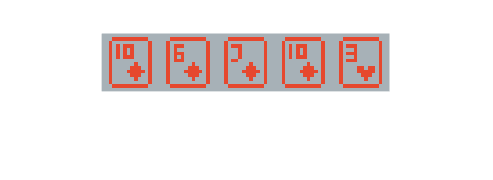

%Set background color of the scene to OSU Grey
card_scene.background_color = [167, 177, 183]; 


%Display cards on the new background
drawScene(card_scene, card_sprites)

If, however, the card faces were displayed over the top of sprite 2, then they become white cards with colorful markings on top of the background color. If, instead, the sprite in the background is the green card back from sprite 6, this could be used to highlight a card.

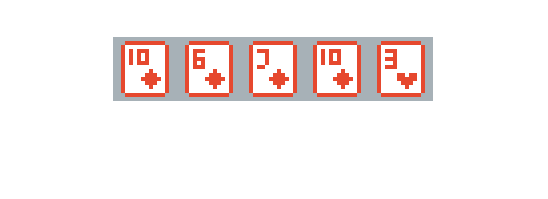


%Call out useful background sprites
plainCardBack = 2;
highlight = 6;

%Create an extra layer of sprites using these backing colors
%Both layers must be the same size.
cardBGC = ones(1,length(card_sprites)) * plainCardBack;
drawScene(card_scene, cardBGC, card_sprites)

There are many different applications to layering sprites. The drawScene function will throw an error and fail, however, if the two matrixes do not have the same dimensions (i.e. here, both are 1x5).

You Try It #4:

Write some code to accomplish the following task:

Display a hand of 5 cards using only one layer of sprites.

Get a mouse input from the user.

If the left mouse button is clicked, add a white card backdrop to just the card clicked

Otherwise, add a white backdrop to all the cards and highlight the card clicked.

Display they layered sprites.

%Display 5 random cards
%Let the user choose one
% Add a white back to that one
% OR highlight one
% And add a white back to the rest.